# Program 4 - SVD macierzy prostokatnej

Autor: Katarzyna Wesołowska, Jan Dworak

Dekompozycję SVD macierzy A odtwarzamy na dwa sposoby: 

1) startując od macierzy$A*A^T$ i jej wektorów własnych U, 

2) startując od macierzy $A^T*A$ i jej wektorów własnych V.

Używamy macierzy prostokątnej 2x3 w postaci $A=\left[\begin{array}{ccc}
1 & 2 & 0\\
2 & 0 & 2
\end{array}\right]$

clear; clc; close all;
format short g;

## 1. Definicja macierzy prostokatnej A

Wybieramy macierz testową A.

A = [1 2 0;
     2 0 2];

[n, m] = size(A);

fprintf('Rozmiar macierzy A: n = %d, m = %d\n\n', n, m);

Rozmiar macierzy A: n = 2, m = 3



disp('Macierz A:');

Macierz A:


disp(A);

     1     2     0
     2     0     2



## Wizualizacja macierzy A

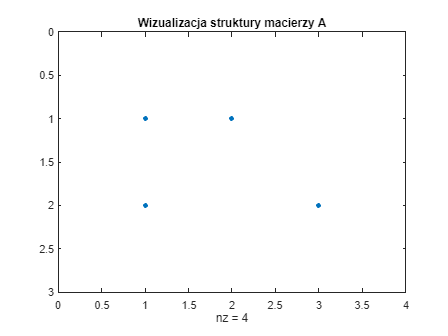

figure('Name', 'Macierz A');
spy(A);
title('Wizualizacja struktury macierzy A');

Funkcja `spy(A)` pokazuje, w których miejscach macierzy znajdują się elementy różne od zera. Kropki na wykresie oznaczają niezerowe wartości macierzy A.

## 2. Obliczenie macierzy $A*A^T$

Obliczamy macierz $A*A^T$. Ponieważ macierz A ma rozmiar 2×3 wynik tego mnożenia ma rozmiar 2x2.

AAT = A * A.';

disp("Macierz A*A':");

Macierz A*A':


disp(AAT);

     5     2
     2     8



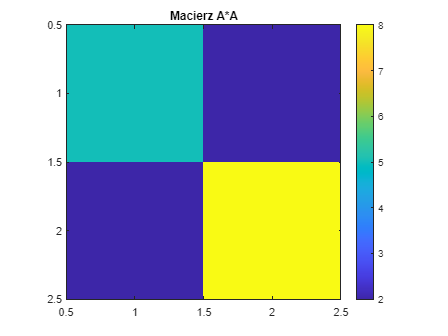


figure('Name', 'Macierz A*A');
imagesc(AAT); colorbar;
axis equal tight;
title('Macierz A*A');

Otrzymano macierz $AA^T=\left[\begin{array}{ccc}
5& 2 \\
2 & 8
\end{array}\right]$. Jest ona symetryczna. To ważne, ponieważ dla macierzy symetrycznej wartości własne są rzeczywiste, a wektory własne można traktować jako prostopadłe kierunki.

Wykres kolorowy pokazuje wartości elementów macierzy.

## 3. Wartosci $\lambda _i
$ i wektory wlasne macierzy $A*A^T$

Korzystamy z funkcji `eig`, która oblicza wartości własne oraz odpowiadające im wektory własne. W tym miejscu szukamy kierunków, które później utworzą macierz U w rozkładzie SVD. Następnie sortujemy wartości własne od największej do najmniejszej, ponieważ w SVD wartości singularne zwykle zapisuje się malejąco.

[U_AAT_raw, D_AAT_raw] = eig(AAT);
lambda_AAT_raw = diag(D_AAT_raw);

[lambda_AAT, idx_AAT] = sort(real(lambda_AAT_raw), 'descend');
U_AAT = real(U_AAT_raw(:, idx_AAT));
U_AAT = normalize_column_signs(U_AAT);
D_AAT = diag(lambda_AAT);

disp("Posortowane wartosci wlasne macierzy A*A':");

Posortowane wartosci wlasne macierzy A*A':


disp(lambda_AAT);

     9
     4




disp("Macierz wektorow wlasnych U otrzymana z A*A':");

Macierz wektorow wlasnych U otrzymana z A*A':


disp(U_AAT);

      0.44721      0.89443
      0.89443     -0.44721



Otrzymano wartości własne: $\lambda_1=9,\quad \lambda_2=4$ oraz odpowiadające im wektory własne, które tworzą macierz $U=\left[\begin{array}{cc}
0.44721 & 0.89443\\
0.89443 & -0.44721
\end{array}\right]$. Kolumny tej macierzy są lewymi wektorami singularnymi. Mówią one, w jakich kierunkach w przestrzeni wynikowej działa macierz A.

## 4. Konstrukcja macierzy U oraz diagonalnej macierzy S z pierwiastkow $\lambda_i
$

Z wartości własnych macierzy $AA^T$ obliczamy wartości singularne, biorąc z nich pierwiastki. Następnie wpisujemy je na przekątną macierzy S. Macierz U tworzą wcześniej obliczone wektory własne macierzy$AA^T$.

sing_vals_from_AAT = sqrt(max(lambda_AAT, 0));
S_from_AAT = zeros(n, m);
S_from_AAT(1:min(n, m), 1:min(n, m)) = diag(sing_vals_from_AAT(1:min(n, m)));

disp("Wartosci singularne sigma_i uzyskane z A*A':");

Wartosci singularne sigma_i uzyskane z A*A':


disp(sing_vals_from_AAT);

     3
     2




disp("Macierz U (z A*A'):");

Macierz U (z A*A'):


disp(U_AAT);

      0.44721      0.89443
      0.89443     -0.44721




disp("Macierz S (z pierwiastkow wartosci wlasnych A*A'):");

Macierz S (z pierwiastkow wartosci wlasnych A*A'):


disp(S_from_AAT);

     3     0     0
     0     2     0



Otrzymane wartości singularne to: $\sigma_1=3,\quad \sigma_2=2$. Są one pierwiastkami z wartości własnych macierzy $AA^T$: $\sqrt{9}=3,\quad \sqrt{4}=2$. 

Następnie wpisujemy je na przekątną macierzy S, która pokazuje, jak mocno macierz A rozciąga przestrzeń w poszczególnych kierunkach.

## 5. Wyznaczenie macierzy V z wlasnosci $V = A^T * U * S^{-1}$

Mając macierz U oraz wartości singularne, możemy obliczyć macierz V. W praktyce nie liczymy całej odwrotności macierzy S, ponieważ S nie jest macierzą kwadratową. Zamiast tego liczymy kolejne kolumny macierzy V ze wzoru:$v_i=\frac{A^Tu_i}{\sigma_i}$. Oznacza to, że dla każdego niezerowego $\sigma_i$ bierzemy odpowiedni wektor $u_i
$, mnożymy go przez $A^T$, a następnie dzielimy przez wartość singularną.

Ponieważ macierz A ma trzy kolumny, macierz V musi mieć trzy kolumny. Brakujący trzeci wektor odpowiada wartości singularnej równej zero. Tego wektora nie wolno liczyć przez dzielenie, ponieważ nie można dzielić przez zero. Dlatego trzeci wektor dobieramy z jądra macierzy A, czyli z przestrzeni rozwiązań równania Ax=0.

Dzięki temu macierz VVV jest kompletna i ortonormalna.

tol = 1e-12;
r = sum(sing_vals_from_AAT > tol);

V_from_AAT = zeros(m, m);
% Ta pętla oblicza kolejne kolumny macierzy V
% Dla każdej niezerowej wartości singularnej sigma_i używamy wzoru:
% v_i = A' * u_i / sigma_i.
% Liczymy tylko dla sigma_i różnych od zera, żeby nie dzielić przez zero.
for i = 1:r
    V_from_AAT(:, i) = (A.' * U_AAT(:, i)) / sing_vals_from_AAT(i);
end

% Dopełnienie bazy przez wektory własne odpowiadające zerowym wartościom
% własnym macierzy A'*A.
[V_ATA_raw_for_completion, D_ATA_raw_for_completion] = eig(A' * A);
lambda_ATA_for_completion = diag(D_ATA_raw_for_completion);
[lambda_ATA_comp, idx_ATA_comp] = sort(real(lambda_ATA_for_completion), 'descend');
V_ATA_for_completion = real(V_ATA_raw_for_completion(:, idx_ATA_comp));
V_ATA_for_completion = normalize_column_signs(V_ATA_for_completion);

if r < m
    V_from_AAT(:, r+1:m) = V_ATA_for_completion(:, r+1:m);
end

V_from_AAT = orthonormalize_columns(V_from_AAT);
V_from_AAT = normalize_column_signs(V_from_AAT);

disp('Macierz V (z dopelnieniem dla sigma=0):');

Macierz V (z dopelnieniem dla sigma=0):



disp(V_from_AAT);

      0.74536   4.8443e-17      0.66667
      0.29814      0.89443     -0.33333
      0.59628     -0.44721     -0.66667



Otrzymano macierz $V=\left[\begin{array}{ccc}
0.74536 & 0 & 0.66667\\
0.29814 & 0.89443 & -0.33333\\
0.59628 & -0.44721 & -0.66667
\end{array}\right]$. Kolumny tej macierzy są prawymi wektorami singularnymi $v_1, v_2, v_3$. Pierwsze dwie kolumny wynikają z niezerowych wartości singularnych, a trzecia kolumna opisuje kierunek należący do jądra macierzy A.

## 6. Wypisanie macierzy $V^T$

disp('Macierz V^T:');

Macierz V^T:


disp(V_from_AAT.');

      0.74536      0.29814      0.59628
   4.8443e-17      0.89443     -0.44721
      0.66667     -0.33333     -0.66667



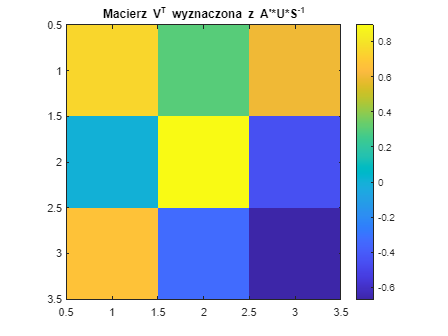


figure('Name', 'Macierz V^T z metody A*A''');
imagesc(V_from_AAT.'); colorbar;
axis equal tight;
title('Macierz V^T wyznaczona z A''*U*S^{-1}');

Otrzymana macierz $V^T$ ma rozmiar 3x3. Jej wiersze są kolejnymi wektorami $v_1^T, v_2^T, v_3^T$. 

Sprawdzamy, jak dobrze działa złożenie $A = U*S*V^T
$.

A_rec_1 = U_AAT * S_from_AAT * V_from_AAT.';
err_rec_1 = norm(A - A_rec_1, 'fro');

fprintf('Blad rekonstrukcji = %.3e\n\n', err_rec_1);

Blad rekonstrukcji = 5.551e-16



Bardzo mała wartość błędu numerycznego, więc można go traktować jako zero.

## 7. Obliczenie i wypisanie macierzy $A^T*A$

Obliczamy macierz $A^T*A$, która ma rozmiar 3×3. Następnie wyznaczamy jej wartości własne oraz wektory własne. Wektory własne tej macierzy tworzą macierz V, czyli macierz prawych wektorów singularnych. 

ATA = A.' * A;

disp('Macierz A''*A:');

Macierz A'*A:


disp(ATA);

     5     2     4
     2     4     0
     4     0     4



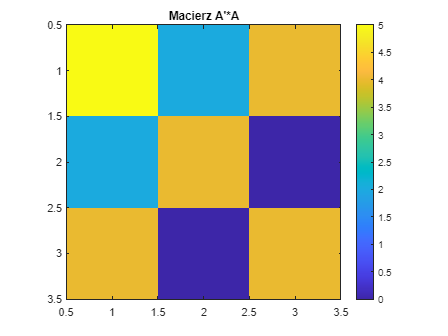


figure('Name', 'Macierz A''*A');
imagesc(ATA); colorbar;
axis equal tight;
title('Macierz A''*A');

Otrzymaliśmy macierz $A^TA=\left[\begin{array}{cc}
5 & 2 & 4\\
2 & 4 &0\\
4 & 0 & 4
\end{array}\right]$. Ta macierz również jest symetryczna, dlatego jej wartości własne są rzeczywiste, a wektory własne można uporządkować w ortonormalną bazę.

## 8. Wartosci i wektory wlasne macierzy $A^T*A$

Wartości własne sortujemy malejąco, aby odpowiadały kolejnym wartościom singularnym.

[V_ATA_raw, D_ATA_raw] = eig(ATA);
lambda_ATA_raw = diag(D_ATA_raw);

[lambda_ATA, idx_ATA] = sort(real(lambda_ATA_raw), 'descend');
V_ATA = real(V_ATA_raw(:, idx_ATA));
V_ATA = normalize_column_signs(V_ATA);
D_ATA = diag(lambda_ATA);

disp('Posortowane wartosci wlasne macierzy A''*A:');

Posortowane wartosci wlasne macierzy A'*A:


disp(lambda_ATA);

            9
            4
  -3.3307e-16




disp('Macierz wektorow wlasnych V otrzymana z A''*A:');

Macierz wektorow wlasnych V otrzymana z A'*A:


disp(V_ATA);

      0.74536            0      0.66667
      0.29814      0.89443     -0.33333
      0.59628     -0.44721     -0.66667



Trzecia wartość może pojawić się jako bardzo mała liczba ujemna, która jest błędem numerycznym wynikający z obliczeń komputerowych. Traktujemy ją jako zero.

## 9. Konstrukcja macierzy V oraz diagonalnej macierzy S z pierwiastkow $\lambda_i
$

Z wartości własnych macierzy $A^TA$ obliczamy wartości singularne, biorąc z nich pierwiastki. Wektory własne macierzy $A^TA$ tworzą macierz V. Następnie wypisujemy macierz $V^T$, czyli wektory $v_i$� zapisane wierszami. Następnie tworzymy macierz S, wpisując wartości singularne na przekątną.

sing_vals_from_ATA = sqrt(max(lambda_ATA, 0));
S_from_ATA = zeros(n, m);
S_from_ATA(1:min(n, m), 1:min(n, m)) = diag(sing_vals_from_ATA(1:min(n, m)));

disp('Wartosci singularne sigma_i uzyskane z A''*A:');

Wartosci singularne sigma_i uzyskane z A'*A:


disp(sing_vals_from_ATA);

     3
     2
     0




disp('Macierz [V1 V2 ... Vm]^T (czyli V^T) z A''*A:');

Macierz [V1 V2 ... Vm]^T (czyli V^T) z A'*A:


disp(V_ATA.');

      0.74536      0.29814      0.59628
            0      0.89443     -0.44721
      0.66667     -0.33333     -0.66667




disp('Macierz S (z pierwiastkow wartosci wlasnych A''*A):');

Macierz S (z pierwiastkow wartosci wlasnych A'*A):


disp(S_from_ATA);

     3     0     0
     0     2     0



Otrzymane wartości singularne to:$\sigma_1=3,\quad \sigma_2=2,\quad \sigma_3=0$. Dwie pierwsze wartości są niezerowe i trafiają na przekątną macierzy S. Trzecia wartość singularna wynosi zero, więc oznacza kierunek, który jest „spłaszczany” przez macierz A do zera.

## 10. Wyznaczenie macierzy U z wlasnosci $U = A^T * V * S^{-1}$

Macierz U wyznaczamy ze wzoru: $U=AVS^{-1}$. Podobnie jak wcześniej nie dzielimy przez zerową wartość singularną. Dla każdej niezerowej wartości singularnej obliczamy: $u_i=\frac{Av_i}{\sigma_i}$. W tym przykładzie mamy dwie niezerowe wartości singularne, więc otrzymujemy dwie kolumny macierzy U. To wystarcza, ponieważ macierz A ma dwa wiersze, a więc macierz U ma rozmiar 2×2.

U_from_ATA = zeros(n, n);
% Ta pętla oblicza kolejne kolumny macierzy U.
% Używamy wzoru u_i = A * v_i / sigma_i.
% Liczymy tylko dla niezerowych wartości singularnych.
for i = 1:r
    U_from_ATA(:, i) = (A * V_ATA(:, i)) / sing_vals_from_ATA(i);
end

if r < n
    U_from_ATA(:, r+1:n) = U_AAT(:, r+1:n);
end

U_from_ATA = orthonormalize_columns(U_from_ATA);
U_from_ATA = normalize_column_signs(U_from_ATA);

disp('Macierz U wyznaczona z A*V*S^{-1}:');

Macierz U wyznaczona z A*V*S^{-1}:


disp(U_from_ATA);

      0.44721      0.89443
      0.89443     -0.44721



## 11. Wypisanie macierzy [U1 U2 ... Un]

W tym punkcie pokazujemy macierz U złożoną z kolejnych lewych wektorów singularnych zapisanych w kolumnach.

disp('Macierz [U1 U2 ... Un]:');

Macierz [U1 U2 ... Un]:


disp(U_from_ATA);

      0.44721      0.89443
      0.89443     -0.44721



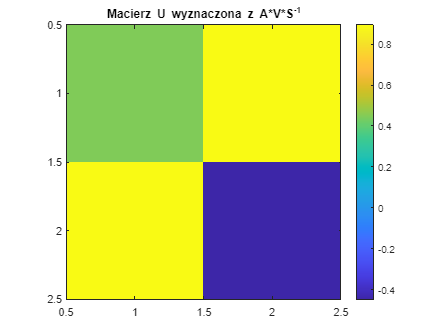


figure('Name', 'Macierz U z metody A''*A');
imagesc(U_from_ATA); colorbar;
axis equal tight;
title('Macierz U wyznaczona z A*V*S^{-1}');

Ponownie weryfikujemy złożenie $A = U*S*V^T$.

A_rec_2 = U_from_ATA * S_from_ATA * V_ATA.';
err_rec_2 = norm(A - A_rec_2, 'fro');

fprintf('Blad rekonstrukcji ||A - U*S*V''||_F = %.3e\n\n', err_rec_2);

Blad rekonstrukcji ||A - U*S*V'||_F = 4.003e-16



Błąd bardzo mały. Traktujemy jako 0.

## 12. Porownanie obu dekompozycji

Obie drogi powinny prowadzić do tej samej dekompozycji SVD z dokładnością numeryczną.

fprintf('--- Porownanie obu dekompozycji ---\n');

--- Porownanie obu dekompozycji ---


fprintf('Wartosci singularne z A*A'':\n');

Wartosci singularne z A*A':


disp(sing_vals_from_AAT.');

     3     2




fprintf('Wartosci singularne z A''*A:\n');

Wartosci singularne z A'*A:


disp(sing_vals_from_ATA(1:min(n,m)).');

     3     2




fprintf('Roznica miedzy wartosciami singularnymi: %.3e\n', ...
    norm(sing_vals_from_AAT(1:min(n,m)) - sing_vals_from_ATA(1:min(n,m)), inf));

Roznica miedzy wartosciami singularnymi: 0.000e+00


fprintf('Blad rekonstrukcji metody 1: %.3e\n', err_rec_1);

Blad rekonstrukcji metody 1: 5.551e-16


fprintf('Blad rekonstrukcji metody 2: %.3e\n\n', err_rec_2);

Blad rekonstrukcji metody 2: 4.003e-16



## Porownanie z wynikiem Matlab

[U_builtin, S_builtin, V_builtin] = svd(A);
err_builtin = norm(A - U_builtin*S_builtin*V_builtin.', 'fro');

disp('U z funkcji svd(A):');

U z funkcji svd(A):


disp(U_builtin);

      0.44721      0.89443
      0.89443     -0.44721




disp('S z funkcji svd(A):');

S z funkcji svd(A):


disp(S_builtin);

     3     0     0
     0     2     0




disp('V z funkcji svd(A):');

V z funkcji svd(A):


disp(V_builtin);

      0.74536            0     -0.66667
      0.29814      0.89443      0.33333
      0.59628     -0.44721      0.66667




fprintf('Blad rekonstrukcji dla wbudowanego svd(A): %.3e\n\n', err_builtin);

Blad rekonstrukcji dla wbudowanego svd(A): 1.116e-15



Różnica między wartościami singularnymi wynosi 0, więc obie metody dają te same wartości singularne.

Błędy rekonstrukcji są bardzo małe, dlatego obie metody poprawnie odtwarzają macierz A.

Macierze U i V mogą jednak różnić się znakami niektórych kolumn. Nie jest to błąd, ponieważ jeśli v jest wektorem własnym, to −v również jest poprawnym wektorem własnym.

Otrzymane zatem tu dekompozycje są równoważne.

## 13. Wymiar obrazu R(A) i jadra N(A)

Obliczamy rząd macierzy A, który jest równy wymiarowi obrazu R(A). Następnie wyznaczamy wymiar jądra N(A) ze wzoru $\dim N(A)=m-{rank}(A)$, gdzie m to liczba kolumn macierzy. 

rankA = rank(A);
nullityA = m - rankA;

fprintf('--- Wymiar obrazu i jadra ---\n');

--- Wymiar obrazu i jadra ---


fprintf('rank(A) = dim R(A) = %d\n', rankA);

rank(A) = dim R(A) = 2


fprintf('dim N(A) = %d\n', nullityA);

dim N(A) = 1


fprintf('Sprawdzenie: dim R(A) + dim N(A) = %d + %d = %d = liczba kolumn m\n\n', ...
    rankA, nullityA, rankA + nullityA);

Sprawdzenie: dim R(A) + dim N(A) = 2 + 1 = 3 = liczba kolumn m




basis_null_A = null(A);
if isempty(basis_null_A)
    disp('Jadro N(A) jest trywialne - brak niezerowych wektorow bazowych.');
else
    disp('Przykladowa baza jadra N(A):');
    disp(basis_null_A);
end

Przykladowa baza jadra N(A):


     -0.66667
      0.33333
      0.66667



Dla naszej macierzy otrzymujemy dim R(A)=2 oraz dim N(A)=1. Ich suma wynosi 3, czyli tyle, ile liczba kolumn macierzy A. Otrzymany wektor bazowy jądra spełnia warunek Ax=0, więc poprawnie opisuje przestrzeń N(A).

## Podsumowanie

Otrzymaliśmy dekompozycję SVD tej samej macierzy A na dwa sposoby:

- pierwszy sposób rozpoczęliśmy od macierzy $A*A^T
$, z której otrzymaliśmy macierz U, 

- drugi sposób rozpoczęliśmy od macierzy $A^T*A$, z której otrzymaliśmy macierz V. 

W obu przypadkach uzyskaliśmy te same wartości singularne. Po złożeniu macierzy $U*S*V^T$ w obu przypadkach otrzymaliśmy z powrotem macierz A, a błędy rekonstrukcji były praktycznie równe zeru. To potwierdza, że dekompozycja SVD została wykonana poprawnie.

Dodatkowo wyznaczono: $dimR(A)=2 , dim N(A) = 1$. Oznacza to, że obraz macierzy A ma wymiar 2, a jądro macierzy A ma wymiar 1.

## Funkcje pomocnicze

Na końcu programu znajdują się dwie funkcje pomocnicze. Nie są one główną częścią metody SVD, ale porządkują wyniki.

Funkcja `normalize_column_signs` ustala znaki kolumn tak, aby wyniki były czytelniejsze i bardziej powtarzalne.

Funkcja `orthonormalize_columns` poprawia kolumny tak, aby były prostopadłe i miały długość 1. Jest to użyte po dopełnieniu brakującego wektora.

function Q = normalize_column_signs(Q)
% Ustala znaki kolumn w sposób deterministyczny:
% pierwszy element o istotnej wartości ma być dodatni.
    tol = 1e-12;
    for j = 1:size(Q,2)
        idx = find(abs(Q(:,j)) > tol, 1, 'first');
        if ~isempty(idx) && Q(idx,j) < 0
            Q(:,j) = -Q(:,j);
        end
    end
end

function Q = orthonormalize_columns(Q)
% Ortonormalizacja kolumn przez rozkład QR.
% Jest używana wyłącznie jako krok porządkujący po dopełnieniu bazy.
    [Q, ~] = qr(Q, 0);
end